### Damian Cabral

## Bottle Rocket Modeling With ODE45

clc;
close all
clear;


#### Constants and Intial State Vector

% For 80m launch:
% Angle = 45 [deg], Pgage = 70 [psi] or 482633 [Pa], 
% P0(gage + ambient) = 82.1 [psi] or 566059 [Pa],
% Volume of Water = 0.0007 [m^3] (35% of bottle), 
% Drag Coefficient = 0.5

Db = .105;              % Diamter of bottle [m]
Dt = 0.021;             % Diameter of throat [m]
Mbottle = 0.15;         % Mass of bottle [kg]
gravity = 9.81;         % Gravity [m/s^2]
Vbottle = 0.002;        % Volume of bottle [m^3]
Vwater = 0.0007;        % Initial volume of water in bottle [m^3]
p_amb = 83426.56;       % Ambient pressure [Pa] (12.1 [psi])
p0 = 482633 + p_amb;    % Initial pressure of air in bottle (gage + ambient) [Pa] 
rhoW = 1000;            % Density of water [kg/m^3]
rhoA = 0.961;           % Density of ambient air [kg/m^3]
Cd = 0.8;               % Discharge coefficient
CD = 0.5;               % Drag Coefficient
R = 287;                % Gas Constant [J/(kg*K)]
T0air = 300;            % Initial Temperature of Air [K]
ls = 0.5;               % Length of test stand [m]
g = 1.4;                % Specific heat ratio
theta = 45;             % Angle of Launch [degrees]

V0air = Vbottle - Vwater; % Inital volume of air [m^3]
M0air = (p0 * V0air) / (R * T0air); % Intial mass of air in bottle [kg]
Ab = (pi/4)*(Db)^2; % Cross-Sectional Area of bottle [m^2]
At = (pi/4)*(Dt)^2; % Cross-Sectional Area of throat [m^2]

% Constants to be passed to ODE45
C = [gravity; Vbottle; p0; p_amb; rhoW; rhoA; Ab; At; Cd; CD; V0air; R; theta; ls; g; M0air];

r = [0; 0.25]; % Initial position
vx = 0; % Initial velocity in the x-dir
vz = 0; % Initial velocity in the z-dir
Vair = V0air; % Volume of air in bottle
Mair = M0air; % Mass of air in bottle
Mrocket = Mbottle + (rhoW * Vwater) + Mair; % Total mass of rocket

X = [r; vx; vz; Mrocket; Mair; Vair]; % Initial state vector for ODE45
tspan = [0 5]; % time span

#### ODE 45

[t, y] = ode45(@(t, y, F) odefunc(t, y, C), tspan, X);

#### Thrust Through Flight and Phase Change

F = ones([size(y, 2) 1]);
phase = ones([size(y, 2) 1]);

% Finds thrust and phases through flight
for i = 1:size(y)
    [~, F(i), phase(i)] = odefunc(t(i), y(i, :), C); 
end

phase1 = find(phase == 1);      % Find indices of y array in phase 1
phase2 = find(phase == 2);      % Find indices of y array in phase 2

#### Plot

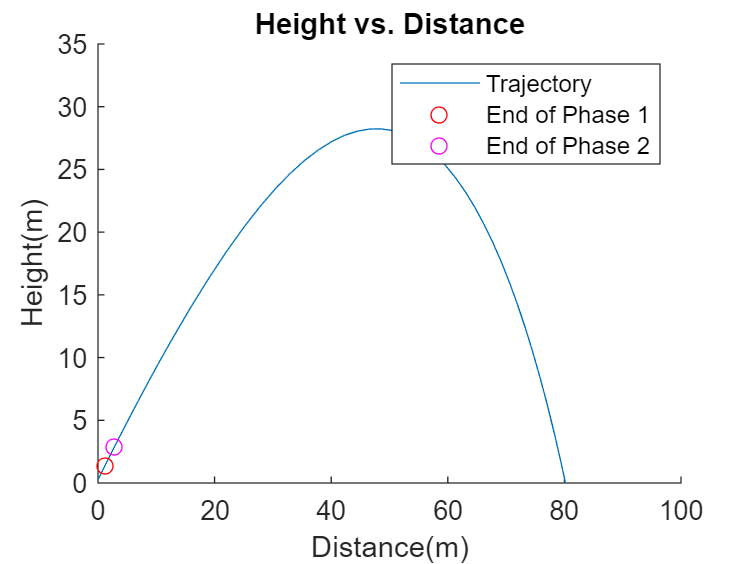

figure;
hold on
plot(y(:, 1), y(:, 2));
plot(y(phase1(end), 1), y(phase1(end), 2), 'o', 'Color', 'r');
plot(y(phase2(end), 1), y(phase2(end), 2), 'o', 'Color','m');
title('Height vs. Distance');
xlabel('Distance(m)');
ylabel('Height(m)');
legend('Trajectory', 'End of Phase 1', 'End of Phase 2');
ylim([0, 35]);

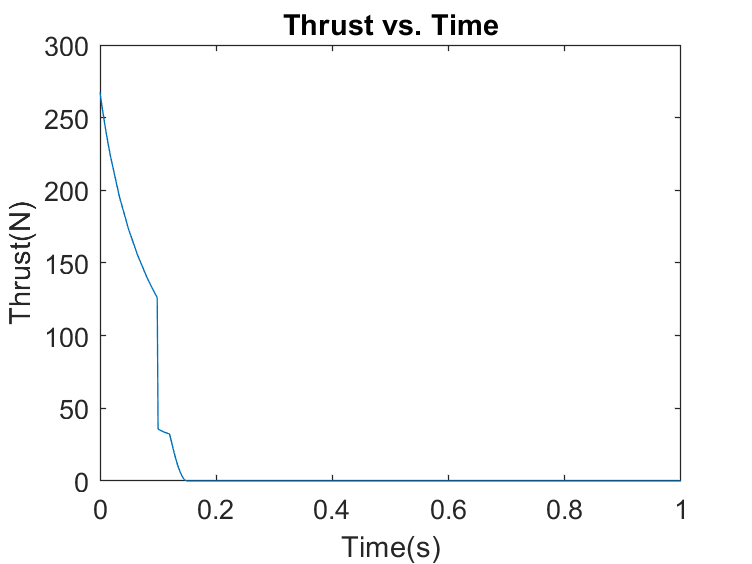


figure;
plot(t(1:end), F);
title('Thrust vs. Time')
ylabel('Thrust(N)');
xlabel('Time(s)');
xlim(0:1)